## TDOA Simulación

% Parámetros de la simulación
range_s = 30; %Alcance máximo de las estaciones terrenas
range_T = 300; %Alcance máximo del satélite
c = 3e8;    %Constante que indica la velocidad de la luz 
M = 8;      %Número de estaciones
E = linspace(30,0.1,20);
in_est_error = 20;  % Error inical estimado en metros
trials = 3;  % Número de experimentos
fail_thr = 1e3;   % Umbral que marca el éxito de la estimación
RMSE = zeros(length(E),1);
for m=1:length(E)
    rmse = zeros(trials,1);
    err_std = E(m)*1e-10; % Error de la medición de TDOA en segundos 
    for k=1:trials % Bucle con el número de experimentos
        % Posición de las estaciones terrenas
        P = zeros(3,M); 
        for ii=1:M
            P(:,ii)=range_s*2*(rand(3,1)-0.5);
        end
        
        p_T = range_T*2*(rand(3,1)-0.5);   % Vector de posción del satélite
        
        %Cálculo de TDOA (simulación de los tiempos de llegada a cada estación)
        dummy = repmat(p_T,1,M)-P;
        toa = zeros(M,1);  
        for ii = 1:M % Cada estación recibe a un tiempo diferente
            toa(ii) = norm(dummy(:,ii))/c;
        end
        
        tdoa = toa-toa(1); tdoa(1)=[];
        tdoa = tdoa + err_std*randn(M-1,1);

## Solución lineal

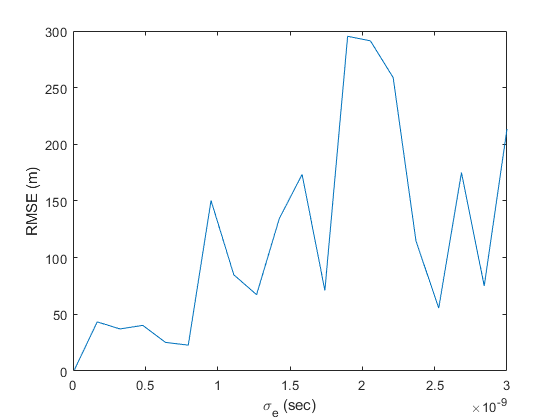

        p_1 = P(:,1);
        dummy = P(:,2:M)';
        A = 2*[(p_1(1)-dummy(:,1)), (p_1(2)-dummy(:,2)), (p_1(3)-dummy(:,3)), -c*tdoa];
        b = (c*tdoa).^2 + norm(p_1)^2 - sum((dummy.^2),2);
        x_lin = pinv(A)*b;
        rmse(k) = norm(p_T-x_lin(1:3))^2;
        
    end
    fails = sum(rmse > fail_thr^2);
    RMSE(m) = sqrt(mean(rmse(rmse < fail_thr^2)));
end

figure
plot(E*1e-10,RMSE);
ylabel('RMSE (m)');
xlabel('\sigma_e (sec)')

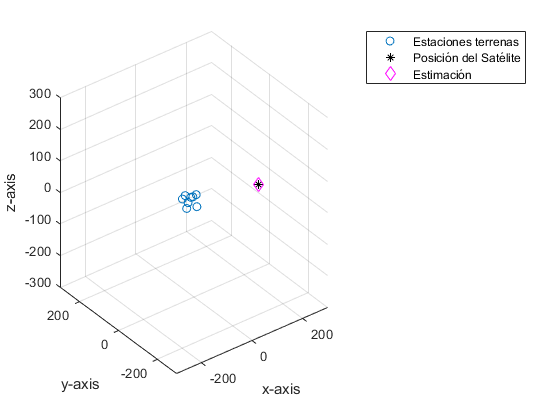

figure
plot3(P(1,:), P(2,:),P(3,:),'o'); 

hold on;

plot3(p_T(1), p_T(2),p_T(3),'k*');
xlim([-range_T range_T]);ylim([-range_T range_T]);zlim([-range_T range_T]);
xlabel('x-axis'); ylabel('y-axis'); zlabel('z-axis');

plot3(x_lin(1), x_lin(2),x_lin(3),'md','MarkerSize',7.75);

legend('Estaciones terrenas', 'Posición del Satélite', 'Estimación')
grid on;
hold off;